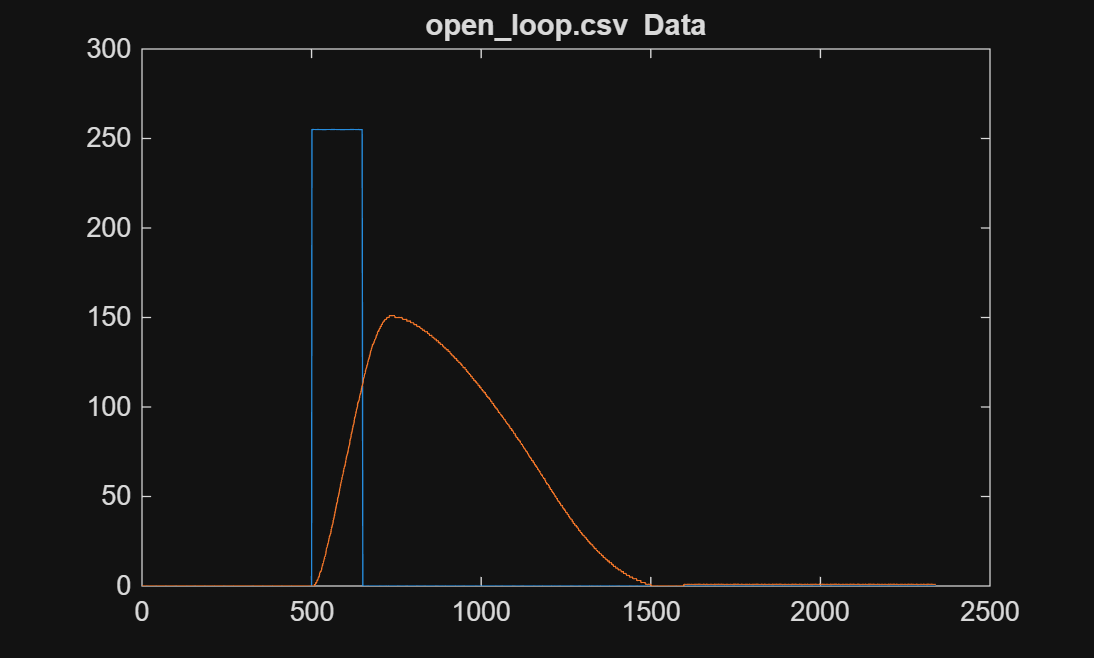

% Import table
step_pwm = readtable("open_loop.csv");
figure;
plot(step_pwm.time, step_pwm.pwmValue, step_pwm.time, step_pwm.position);
title("open\_loop.csv Data");

t_raw = T.time(:) / 1000;         % seconds (time is in ms)
u_raw = T.pwmValue(:);            % PWM command (0..255)
y_raw = T.position(:);            % encoder counts

% Ensure column vectors + sorted time
[t_raw, idx] = sort(t_raw);
u_raw = u_raw(idx);
y_raw = y_raw(idx);

%% 2) Resample to uniform Ts
Ts = median(diff(t_raw));          % ~0.001 s
t = (t_raw(1):Ts:t_raw(end))';

% Input as zero-order hold, output as linear interpolation
u = interp1(t_raw, u_raw, t, "previous", "extrap");
y = interp1(t_raw, y_raw, t, "linear",   "extrap");

% optional: convert counts -> radians (set your encoder CPR!)
% If you don't know CPR yet, keep y in counts for now.
CPR = 2048;                        % <-- CHANGE (counts per revolution)
y = (2*pi/CPR) * y;                % radians

% trim to a clean window (optional but helps)
% Include a bit before the pulse and enough time after to see ring-down
tStart = 0.0;
tEnd   = t(end);
keep = (t >= tStart) & (t <= tEnd);

t = t(keep);
u = u(keep);
y = y(keep);

%% detrend / remove offsets
u = u - u(1);
y = y - y(1);

% If you want input in "duty" instead of 0..255:
u = u / 255;

% build iddata
data = iddata(y, u, Ts, "TimeUnit","s");

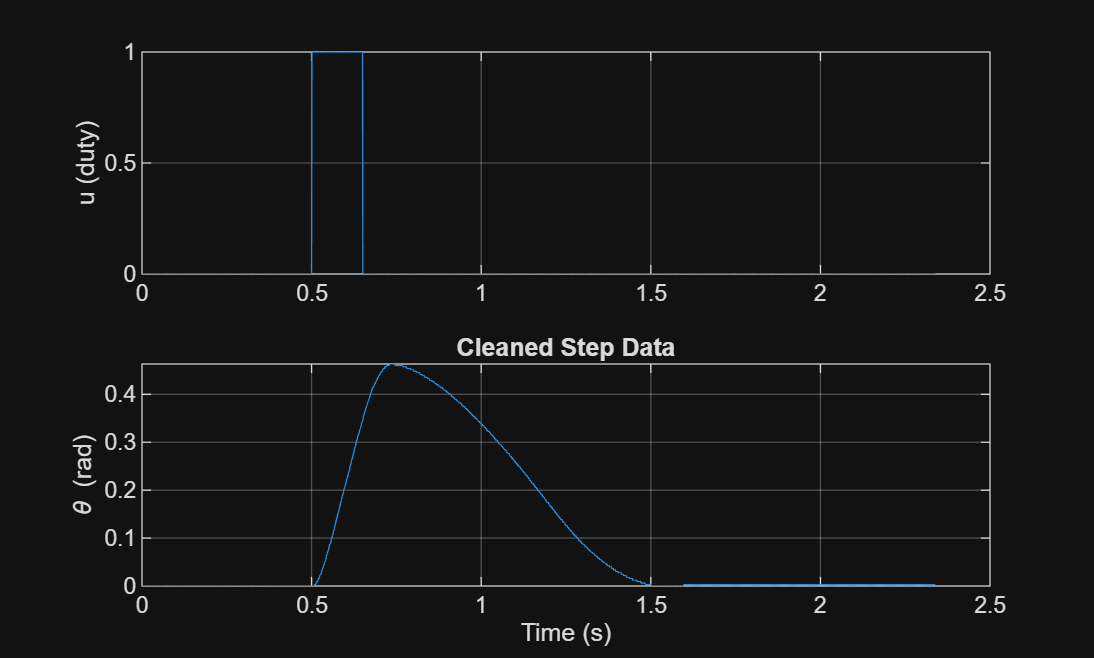

% Plots
figure; subplot(2,1,1); plot(t,u); grid on; ylabel("u (duty)");
subplot(2,1,2); plot(t,y); grid on; ylabel("\theta (rad)"); xlabel("Time (s)");
title("Cleaned Step Data");

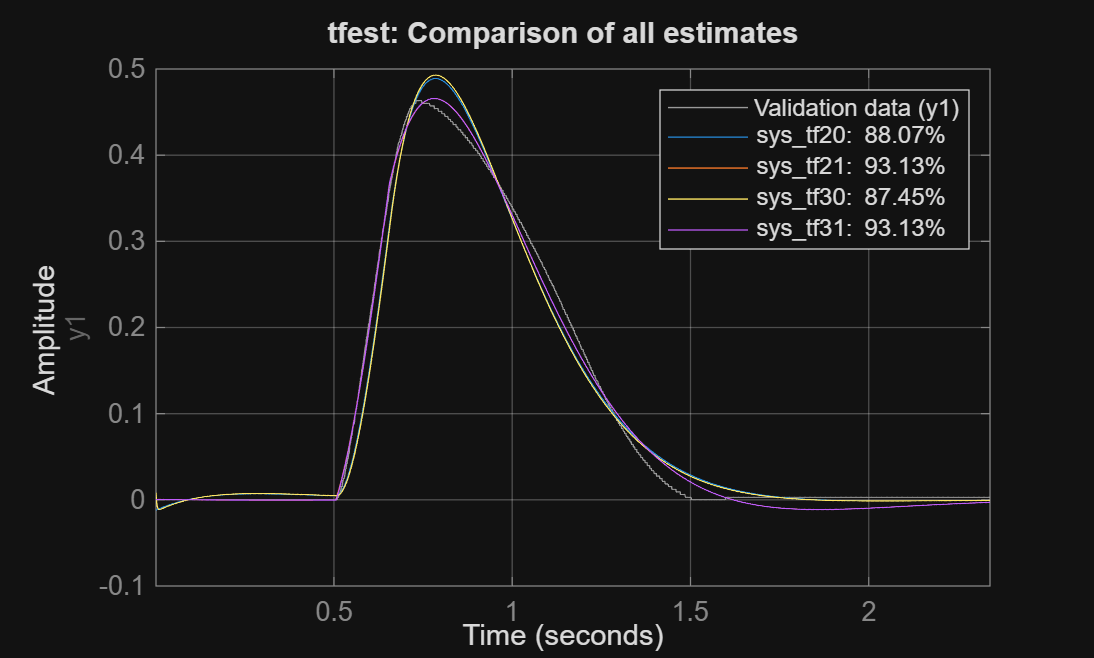


% Estimate models
sys_tf20 = tfest(data, 2, 0, 'InputDelay', 0.003);
sys_tf21 = tfest(data, 2, 1, 'InputDelay', 0.003);
sys_tf30 = tfest(data, 3, 0, 'InputDelay', 0.003);
sys_tf31 = tfest(data, 3, 1, 'InputDelay', 0.003);

figure; compare(data, sys_tf20, sys_tf21,sys_tf30,sys_tf31); grid on;
title("tfest: Comparison of all estimates");

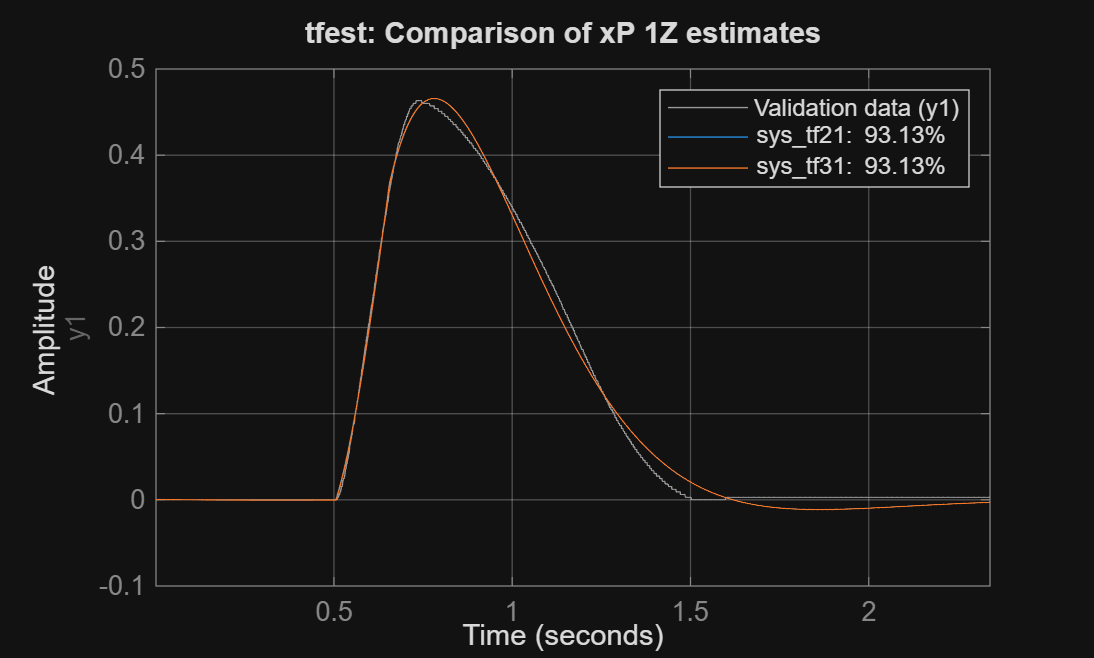


figure; compare(data, sys_tf21, sys_tf31); grid on;
title("tfest: Comparison of xP 1Z estimates");

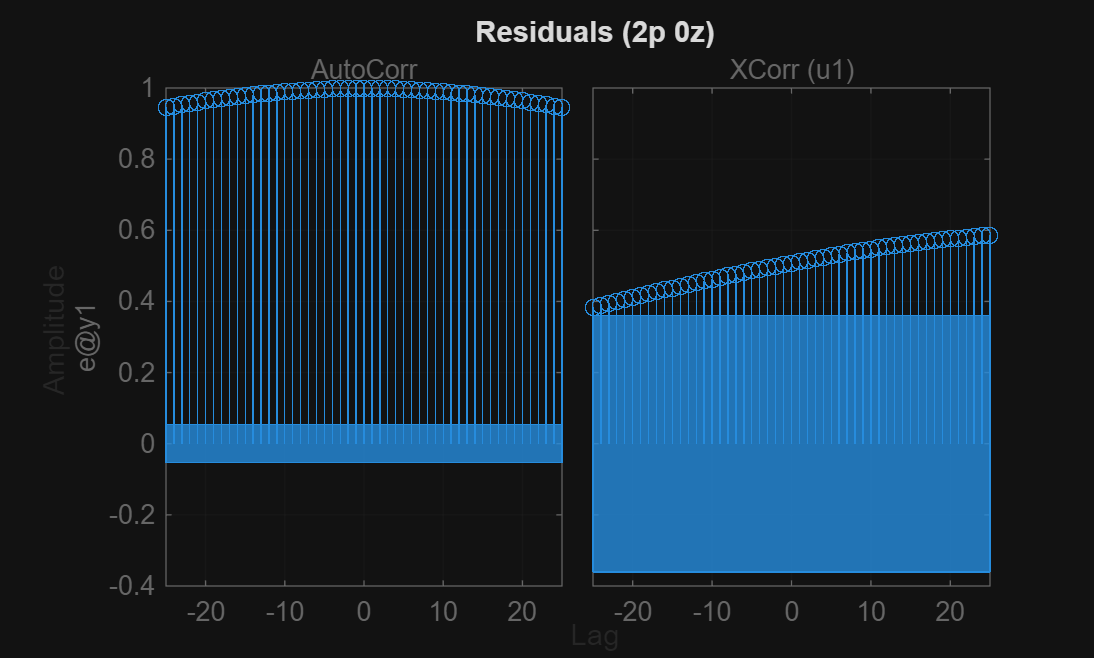


figure; resid(data, sys_tf20); grid on; title("Residuals (2p 0z)");

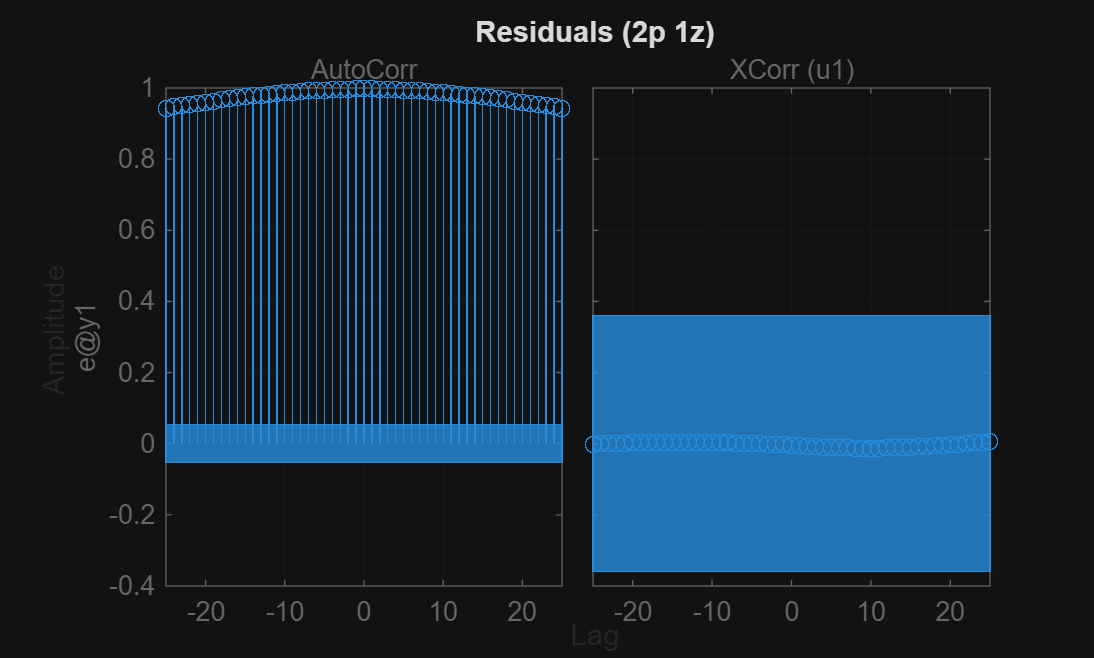

figure; resid(data, sys_tf21); grid on; title("Residuals (2p 1z)");

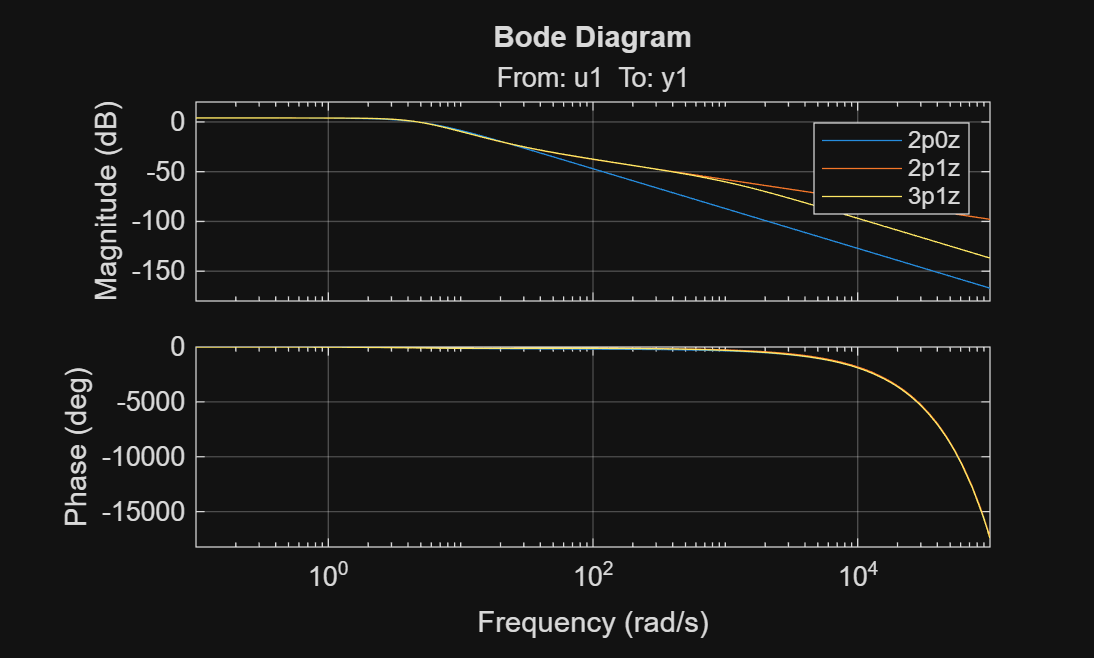

figure; bode(sys_tf20, sys_tf21, sys_tf31); grid on; legend("2p0z","2p1z", "3p1z");

% display selected system
disp("Select 2 poles 1 zero as best fit model");

Select 2 poles 1 zero as best fit model


sys_tf21


sys_tf21 =
 
  From input "u1" to output "y1":
                     1.276 s + 32.18
  exp(-0.003*s) * ---------------------
                  s^2 + 6.905 s + 20.39
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 93.13%                   
FPE: 0.0001159, MSE: 0.0001153                   
 
Model Properties


disp('Damping / natural frequencies for 2p1z model:');

Damping / natural frequencies for 2p1z model:


damp(sys_tf21)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.45e+00 + 2.91e+00i     7.64e-01       4.52e+00         2.90e-01    
 -3.45e+00 - 2.91e+00i     7.64e-01       4.52e+00         2.90e-01    


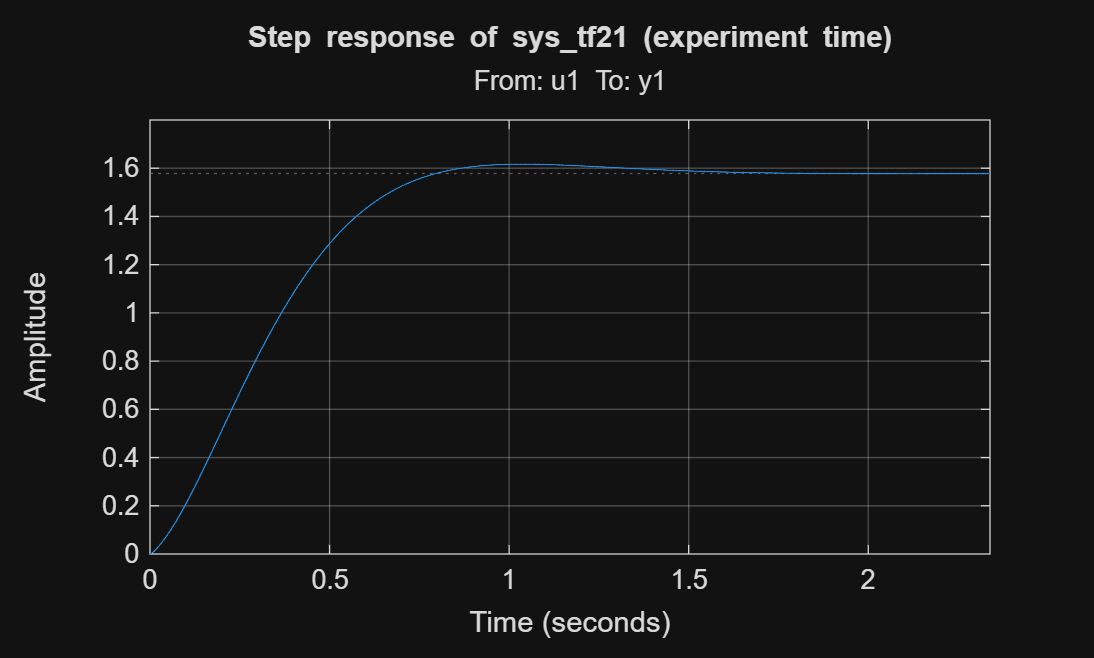

% plot selected system
figure;
step(sys_tf21, t);
grid on;
title('Step response of sys\_tf21 (experiment time)');